Load Data

% โหลดไฟล์ Ground Truth
ld = load("7SegmentGtruth.mat"); % โหลดไฟล์ .mat ที่เก็บข้อมูล Ground Truth (Bounding Boxes และ Labels)
gTruth = ld.gTruth; % ดึงข้อมูล Ground Truth ออกมาใช้งานจากโครงสร้างของไฟล์ที่โหลด

% ระบุชื่อ Label และ Attribute สำหรับการดึงข้อมูล OCR
labelName = "Text"; % ชื่อ Label ที่ระบุใน Image Labeler App
attributeName = "Digits"; % ชื่อ Attribute ที่กำหนดใน Image Labeler App

% สร้าง Datastore จาก Ground Truth
[imds, boxds, txtds] = ocrTrainingData(gTruth, labelName, attributeName);
% - imds: Image Datastore ที่เก็บภาพทั้งหมด
% - boxds: Datastore สำหรับ Bounding Boxes (ตำแหน่งของตัวอักษรในภาพ)
% - txtds: Datastore สำหรับ Labels (ข้อความที่ Annotate ไว้ใน Bounding Boxes)


Analyze Ground Truth Data

% อ่านข้อความทั้งหมดจาก Datastore
allImagesText = txtds.readall; % อ่านข้อความ (Text) จาก Datastore txtds
allText = strjoin(vertcat(allImagesText{:}), ""); % รวมข้อความทั้งหมดจากทุกภาพให้เป็นข้อความเดียว

% หาตัวอักษรที่ไม่ซ้ำกันในชุดข้อมูล
[characterSet, ~, idx] = unique(char(allText)); % ค้นหาตัวอักษรที่ไม่ซ้ำและสร้างดัชนี (Index)

% แสดงชุดตัวอักษรทั้งหมดใน Ground Truth
disp("Ground truth Character Set: " + string(characterSet)); % แสดงตัวอักษรทั้งหมดที่ปรากฏในชุดข้อมูล Ground Truth

Ground truth Character Set: .0123456789


Analyze Dataset Class Distribution

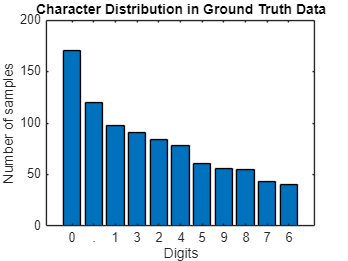

% แปลงชุดตัวอักษร (Character Set) เป็น Cell Array
characterSet = cellstr(characterSet'); % แปลงชุดตัวอักษรจาก String เป็น Cell Array (ทีละตัวอักษร)

% นับจำนวนการปรากฏของแต่ละตัวอักษรในชุดข้อมูล Ground Truth
characterCount = accumarray(idx, 1); % นับจำนวนครั้งที่แต่ละตัวอักษรปรากฏ

% สร้างตาราง (Table) สำหรับเก็บตัวอักษรและจำนวนการปรากฏ
characterCountTbl = table(characterSet, characterCount, ...
    VariableNames=["Character", "Count"]); % ชื่อตาราง "Character" และ "Count"

% เรียงลำดับตารางจากตัวอักษรที่ปรากฏบ่อยที่สุดไปหาน้อยที่สุด
characterCountTbl = sortrows(characterCountTbl, "Count", "descend");

% นับจำนวนตัวอักษรทั้งหมดในชุดข้อมูล
numCharacters = numel(characterSet);

% สร้างกราฟแท่ง (Bar Chart) เพื่อแสดงการกระจายของตัวอักษร
figure
bar(1:numCharacters, characterCountTbl.Count) % กราฟแท่งแสดงจำนวนการปรากฏของตัวอักษร
xticks(1:numCharacters) % กำหนดตำแหน่งแกน X ให้สอดคล้องกับตัวอักษร
xticklabels(characterCountTbl.Character) % ตั้ง Label แกน X เป็นตัวอักษร
xlabel("Digits") % ชื่อแกน X
ylabel("Number of samples") % ชื่อแกน Y
title("Character Distribution in Ground Truth Data") % ชื่อกราฟ

Prepare Data for Training

% รวมข้อมูล Datastore ทั้งหมด
cds = combine(imds, boxds, txtds);

% จำนวนตัวอย่างทั้งหมด
numSamples = numel(imds.Files); % ใช้จำนวนไฟล์ใน imds เป็นจำนวนตัวอย่างทั้งหมด

% สุ่มลำดับข้อมูล
rng(0); % ตั้งค่าการสุ่มให้ผลลัพธ์เหมือนเดิมทุกครั้ง
shuffledIndices = randperm(numSamples); % สุ่มลำดับตัวอย่างทั้งหมด

% กำหนดเปอร์เซ็นต์การแบ่งข้อมูล
trainPercent = 80; % 80% สำหรับ Training Set
valPercent = 10;   % 10% สำหรับ Validation Set
testPercent = 10;  % 10% สำหรับ Test Set

% คำนวณจำนวนตัวอย่างในแต่ละชุด
numTrain = round(trainPercent / 100 * numSamples); % จำนวนตัวอย่างใน Training Set
numVal = round(valPercent / 100 * numSamples);     % จำนวนตัวอย่างใน Validation Set
numTest = numSamples - numTrain - numVal;          % จำนวนตัวอย่างใน Test Set

% แบ่งดัชนีข้อมูลออกเป็นชุด
trainIndices = shuffledIndices(1:numTrain);           % Training Set
valIndices = shuffledIndices(numTrain + 1:numTrain + numVal); % Validation Set
testIndices = shuffledIndices(numTrain + numVal + 1:end);     % Test Set

% สร้าง Datastore ย่อย
cdsTrain = subset(cds, trainIndices); % Training Set
cdsVal = subset(cds, valIndices);     % Validation Set
cdsTest = subset(cds, testIndices);   % Test Set

% แสดงจำนวนตัวอย่างในแต่ละชุด
disp("Number of training samples: " + numTrain);

Number of training samples: 95


disp("Number of validation samples: " + numVal);

Number of validation samples: 12


disp("Number of test samples: " + numTest);

Number of test samples: 12


Train OCR Model

% กำหนดโฟลเดอร์สำหรับเก็บโมเดลที่ฝึกแล้ว
outputDir = "OCRModel";
if ~exist(outputDir, "dir") % ตรวจสอบว่าโฟลเดอร์มีอยู่แล้วหรือไม่
    mkdir(outputDir); % ถ้าไม่มี ให้สร้างโฟลเดอร์ใหม่
end

% กำหนดโฟลเดอร์สำหรับเก็บจุดตรวจสอบ (Checkpoints)
checkpointsDir = "Checkpoints";
if ~exist(checkpointsDir, "dir") % ตรวจสอบว่าโฟลเดอร์มีอยู่แล้วหรือไม่
    mkdir(checkpointsDir); % ถ้าไม่มี ให้สร้างโฟลเดอร์ใหม่
end

% ตั้งค่าตัวเลือกสำหรับการฝึกโมเดล OCR
ocrOptions = ocrTrainingOptions(GradientDecayFactor=0.9,... % กำหนดค่า Gradient Decay Factor สำหรับการปรับปรุงโมเดล
    InitialLearnRate=20e-4,... % อัตราการเรียนรู้เริ่มต้น
    MaxEpochs=15,... % จำนวน Epoch สูงสุด
    VerboseFrequency=100,... % ความถี่ในการแสดงผลระหว่างการฝึก
    OutputLocation=outputDir,... % ตำแหน่งในการบันทึกโมเดลที่ฝึกแล้ว
    CheckpointPath=checkpointsDir,... % ตำแหน่งในการเก็บ Checkpoints
    ValidationData=cdsVal,... % ข้อมูลสำหรับการตรวจสอบ (Validation)
    ValidationFrequency=10); % ความถี่ในการตรวจสอบระหว่างการฝึก

% ตั้งชื่อโมเดลและเลือกโมเดลพื้นฐาน
trainedModelName = "sevenSegmentModel"; % ชื่อโมเดลที่ฝึก
baseModel = "english"; % โมเดลพื้นฐานที่ใช้สำหรับการฝึก

% ฝึกโมเดล OCR ด้วยข้อมูลที่เตรียมไว้
[trainedModel, trainingInfo] = trainOCR(cdsTrain, trainedModelName, baseModel, ocrOptions);

*************************************************************************
Starting OCR training

Model Name: sevenSegmentModel
Base Model: english

Preparing training data... 100.00 % completed.
Preparing validation data... 100.00 % completed.

Character Set: .0123456789

|======================================================================================================================================|
| Epoch | Iteration | Time Elapsed |           Training Statistics           |          Validation Statistics          | Base Learning |
|       |           |  (hh:mm:ss)  |   RMSE   | Character Error | Word Error |   RMSE   | Character Error | Word Error |     Rate      |
|======================================================================================================================================|
|   1   |     1     |   00:00:15   |  18.73   |     100.00      |   100.00   |   0.00   |      0.00       |    0.00    |    0.0020     |
|   1   |    100    |   00:00:21   |   9.2

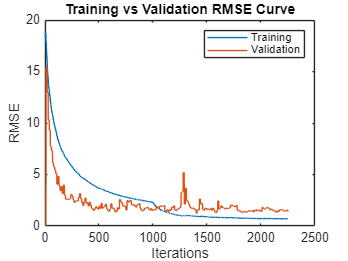


% วาดกราฟแสดง RMSE ระหว่างการฝึกและการตรวจสอบ
figure
plot(trainingInfo.TrainingRMSE); hold on; % วาดกราฟ RMSE ของ Training Set
plot(trainingInfo.ValidationRMSE); % วาดกราฟ RMSE ของ Validation Set
legend(["Training", "Validation"]); % เพิ่มคำอธิบายกราฟ
xlabel("Iterations"); % ชื่อแกน X
ylabel("RMSE"); % ชื่อแกน Y
title("Training vs Validation RMSE Curve"); % ชื่อกราฟ

Evaluate Trained Model Using Test Set

% ใช้โมเดลที่ฝึกแล้วเพื่อทำ OCR บนชุดข้อมูล Test Set
trainedModelResults = ocr(cdsTest, Model=trainedModel); % ใช้ฟังก์ชัน ocr เพื่ออ่านข้อมูลจาก Test Set ด้วยโมเดลที่ฝึกแล้ว

% ประเมินผลโมเดล OCR โดยใช้ Test Set
trainedModelMetrics = evaluateOCR(trainedModelResults, cdsTest); % ใช้ฟังก์ชัน evaluateOCR เพื่อคำนวณค่าความถูกต้องและค่าผิดพลาด

Evaluating ocr results
----------------------
* Selected metrics: character error rate, word error rate.
* Processed 12 images.
* Finalizing... Done.
* Data set metrics:

    CharacterErrorRate    WordErrorRate
    __________________    _____________

         0.16071             0.22917   




% คำนวณความแม่นยำของโมเดล (Test Accuracy)
trainedModelAccuracy = 100 * (1 - trainedModelMetrics.DataSetMetrics.CharacterErrorRate); % แปลงค่าความผิดพลาด (Character Error Rate) เป็นเปอร์เซ็นต์ของความแม่นยำ

% แสดงค่าความแม่นยำของโมเดล
disp("Test accuracy of the trained model = " + trainedModelAccuracy + "%"); % พิมพ์ค่าความแม่นยำใน Command Window

Test accuracy of the trained model = 83.9286%


Recognize Seven-Segment Digits

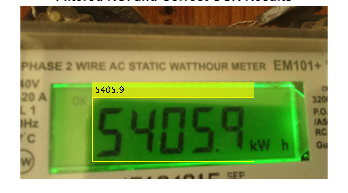

% โหลดภาพ
img = imread('sevSegDisp.jpg'); % เปลี่ยนชื่อไฟล์ให้ตรงกับภาพของคุณ

% ตรวจจับ ROI ทั้งหมดด้วย detectTextCRAFT
bboxes = detectTextCRAFT(img, LinkThreshold=0.01, CharacterThreshold=0.4);

% ขนาดภาพ
imageHeight = size(img, 1);
imageWidth = size(img, 2);

% กรอง ROI และ OCR
filteredBboxes = [];
results = {}; % เก็บผลลัพธ์ OCR ที่กรองแล้ว

for i = 1:size(bboxes, 1)
    % พิกัด ROI
    roi = bboxes(i, :);
    x = roi(1);
    y = roi(2);
    width = roi(3);
    height = roi(4);

    % กรอง ROI โดยใช้ตำแหน่งและลักษณะเฉพาะของตัวเลข 7-segment
    aspectRatio = width / height;
    if y > imageHeight * 0.4 && y < imageHeight * 0.7 ... % ตำแหน่งแนวตั้งตรงกลาง
            && x > imageWidth * 0.2 && x < imageWidth * 0.8 ... % ตำแหน่งแนวนอนตรงกลาง
            && aspectRatio > 1.5 && aspectRatio < 3 ... % อัตราส่วนกว้างยาวคล้ายตัวเลข
            && height > 20 % ความสูงขั้นต่ำของตัวเลข
        filteredBboxes = [filteredBboxes; roi]; % เก็บ ROI

        % ทำ OCR บน ROI นี้
        ocrResults = ocr(img, roi, Model="seven-segment");
        ocrText = strjoin(ocrResults.Words); % รวมคำที่ OCR อ่านได้

        % กรองเฉพาะตัวเลข
        if ~isempty(ocrText) && ~isempty(regexp(ocrText, '^\d+(\.\d+)?$', 'once'))
            results{end+1} = ocrText; % เก็บผลลัพธ์ตัวเลข
        else
            results{end+1} = ''; % ข้ามข้อความที่ไม่ใช่ตัวเลข
        end
    end
end

% ใส่ผลลัพธ์ OCR ลงในภาพ
annotatedImg = insertObjectAnnotation(img, "rectangle", filteredBboxes, results, ...
    "LineWidth", 4, "FontSize", 70, "Color", "yellow");

% แสดงภาพพร้อมผลลัพธ์ OCR ที่กรองแล้ว
figure;
imshow(annotatedImg);
title('Filtered ROI and Correct OCR Results');